We'd like to know what the ice thickness is at that lat/lng (I think it's maybe 150 km from Pole?) so we can start to line up the features in your plots with the surface and bed echoes? Do you have a sense of where to find that information? If not, I'm pretty sure RJ Moser does. Let me know, thanks!

we want to convert your echo strength vs time graph (which is how it's graphed in brightnessCalibration) into an echo strength vs depth graph, at which point we can start to interpret the data more quantitatively

- **brightness = echo strength**

- **where did my depth variable go ?! :(**

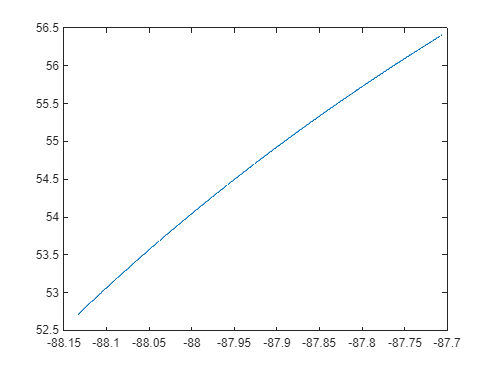

addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_standard\20240105_02\
addpath C:\Users\macaw\Documents\scripts\metadata\rds\2023_Antarctica_BaslerMKB\CSARP_layer\20240105_02\


% load Data_20240105_02_005.mat ;        % layer file
load Data_img_01_20240105_02_005.mat ; % echogram file

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
% fast & slow time explanation: 
%
% fast time is the y axis since that's in terms of the two way travel time of the radar 
% which ofc goes very fast, and slow time is the x axis 
% since that's in terms of the plane's movement, which is relatively slow
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%
%   Latitude: 1 by N double vector where N is slow time (in degrees)
% WGS-84 geodetic latitude coordinate. Always referenced to North. 
% Without motion compensation, represents the location that the trajectory data was processed to. 
% With motion compensation, represents the location of the radar echogram data phase center. 
% It may not be the actual measurement location due to motion compensation 
%
% Data: M x N double array where M is fast time and N is slow time (M row & N columns)
%   measures radad echogram data
%   Units: Relative received power (Watts) 
%
% "fast time is the y axis since that's in terms of the two way travel time of the radar 
% which ofc goes very fast, and slow time is the x axis since 
% that's in terms of the plane's movement, which is relatively slow"
%   - Elijah
%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

plot(Latitude, Longitude) % 1819 size

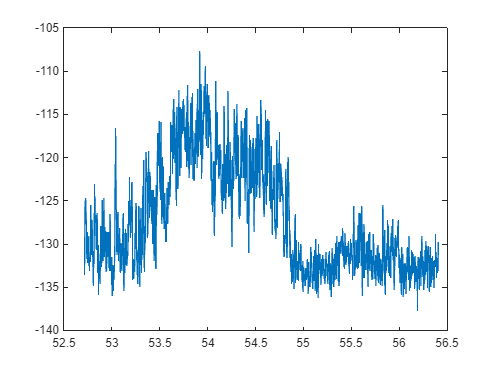

addpath C:\users\macaw\Documents\scripts\matlab\
load brightnessVariables.mat


plot(Longitude, 10*log10(layerIndexBrightness(5, :)))

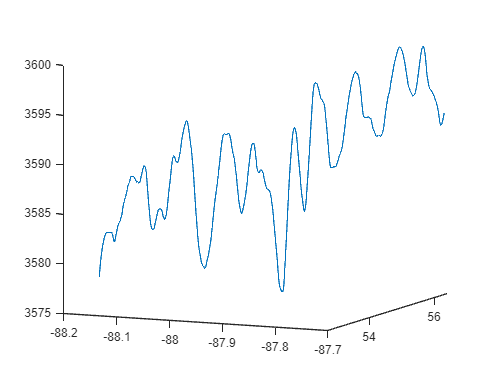

plot3(Latitude,Longitude,Elevation)

view([24.3 9.4])

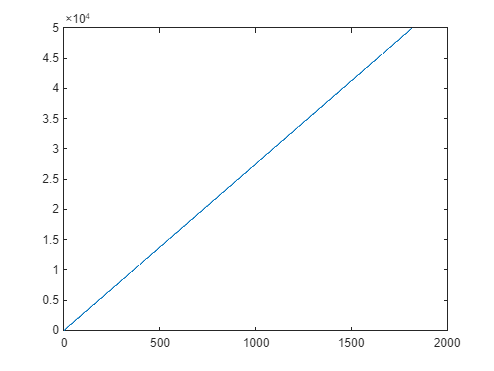



alongTrack = geodetic_to_along_track(Latitude, Longitude, Elevation);

plot(alongTrack)

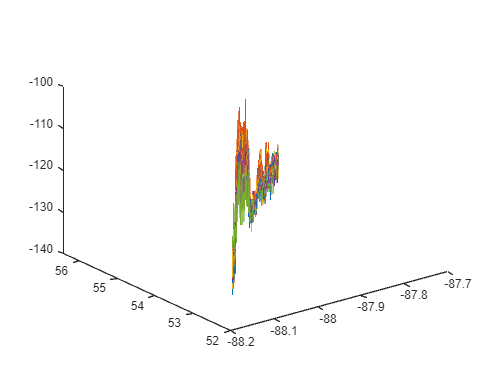


plot3(Latitude, Longitude, 10*log10(layerIndexBrightness))

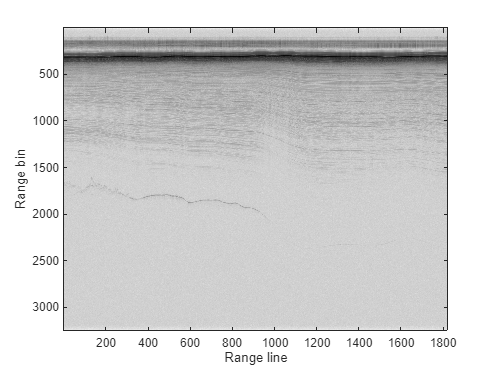

% display echogram as image -> use to pull brightness based on intensity ?
imagesc(lp(Data)); 
colormap(1-gray)
xlabel('Range line'); 
ylabel('Range bin'); 

% range bin + range line values correspond to indices on arrays